## **Espace de solutions**

### **Recuperation des solutions calculées dans le fichier ***Config_Robot_Redondant_Point*

On définit tout d'abord les variables du code puis l'espace de solutions sans conditions de filtrage pour atteindre le point cible est recupéré pour ensuite afficher les differentes configuration articulaires possibles en radian, et en degres

% Charger les solutions depuis le fichier
load('solutionstraj.mat');
final_results(:, 2:6) = rad2deg(final_results(:, 2:6));

% Afficher les résultats finaux
%disp('Résultats finaux (en degrés) :');
%disp(final_results);

% Convertir les angles en radians et ajuster les angles à l'intervalle [-180, 180]
final_results(:, 2:6) = mod(final_results(:, 2:6)+ 180, 360) - 180;

% Afficher les résultats finaux en degrés ajustés
disp('Résultats finaux (en degrés ajustés) :');

Résultats finaux (en degrés ajustés) :



fprintf('| %-7s | %-9s | %-9s | %-9s | %-9s | %-9s | %-11s | %-11s |\n', 'Point', 'Theta1', 'Theta2', 'Theta3', 'Theta4', 'Theta5', 'X_calculé', 'Y_calculé');

| Point   | Theta1    | Theta2    | Theta3    | Theta4    | Theta5    | X_calculé   | Y_calculé   |


disp('__________________________________________________________________________________________________________________');

__________________________________________________________________________________________________________________


for i = 1:size(final_results, 1)
    fprintf('| %-7d | %-9.4f | %-9.4f | %-9.4f | %-9.4f | %-9.4f | %-11.4f | %-11.4f |\n', final_results(i,1), final_results(i,2:6), final_results(i,7:8));
end

| 1       | -47.4643  | 48.6832   | 10.6715   | -13.8256  | 34.1219   | 10.0000     | -0.0000     |
| 1       | -45.9671  | 37.1401   | 17.7158   | 15.9513   | -2.8456   | 10.0000     | -0.0000     |
| 1       | -27.8365  | 54.4804   | -37.7899  | -15.4898  | 52.4793   | 10.0000     | 0.0000      |
| 1       | -36.8364  | 41.6806   | 3.3909    | -26.5069  | 58.2990   | 10.0000     | 0.0000      |
| 1       | -28.7783  | 47.4427   | -24.0451  | -22.6988  | 62.5408   | 10.0000     | 0.0000      |
| 1       | -41.7874  | 53.0605   | 0.5359    | -31.4939  | 50.0385   | 10.0000     | 0.0000      |
| 1       | -33.5848  | 23.5133   | 32.6850   | -33.4886  | 49.1649   | 10.0000     | -0.0000     |
| 1       | -29.1378  | 29.1772   | 16.1370   | -41.9982  | 65.8269   | 10.0000     | 0.0000      |
| 1       | -11.6543  | -4.8854   | 47.1642   | -56.9790  | 60.6550   | 10.0000     | 0.0000      |
| 1       | -38.6930  | 45.5373   | -0.7257   | -22.8637  | 55.6414   | 10.0000     | 0.0000      |


disp('__________________________________________________________________________________________________________________');

__________________________________________________________________________________________________________________


### Variation de theta1 pour chaque solution. Tous les points avec le même numéro de point auront la même couleur dans le graphique.

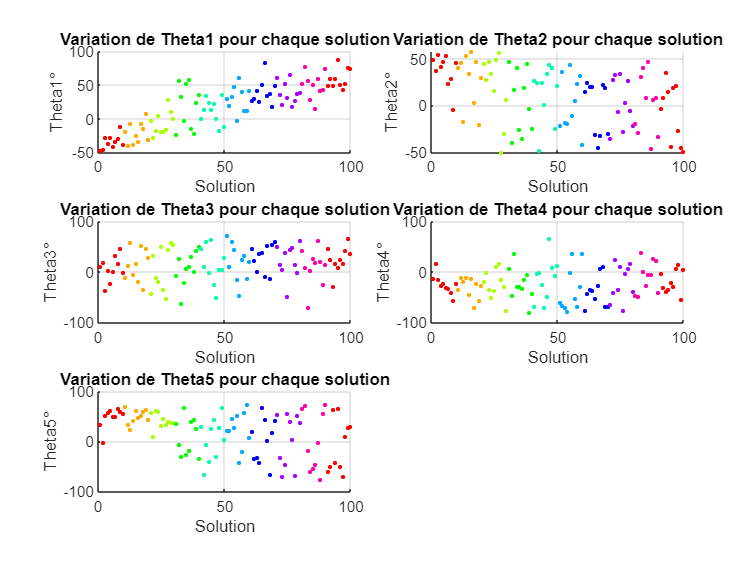

figure;
% Créer un tableau de hachage pour mapper chaque numéro de point à une couleur
unique_colors_map = containers.Map('KeyType', 'double', 'ValueType', 'double');
color_index = 1;

for i = 1:size(final_results, 1)
    point_number = final_results(i, 1); % Numéro de point
    if ~isKey(unique_colors_map, point_number)
        unique_colors_map(point_number) = color_index; % Assigner une nouvelle couleur pour chaque nouveau numéro de point
        color_index = color_index + 1;
    end
end

% Convertir les angles en degrés et ajuster les angles à l'intervalle [-180, 180]
final_results_deg = final_results(:, 2:6);
final_results_deg = mod(final_results_deg + 180, 360) - 180;

% Définir le nombre de lignes et de colonnes pour la grille
num_rows = 3; % Modifier le nombre de lignes selon le nombre de joints
num_cols = 2; % Nombre de colonnes pour afficher les graphiques

% Créer une nouvelle figure
figure;

% Boucle sur chaque angle d'articulation
for joint = 1:5
    % Définir la position du subplot dans la grille
    subplot(num_rows, num_cols, joint);
    
    % Boucle sur chaque solution
    for i = 1:size(final_results, 1)
        point_number = final_results(i, 1); % Numéro de point
        color_index = unique_colors_map(point_number); % Récupérer l'index de couleur pour ce numéro de point

        % Définir la couleur en fonction de l'index récupéré
        color = hsv2rgb([(color_index-1)/(size(unique_colors_map, 1)-1), 1, 1]); % Utiliser l'espace colorimétrique HSV pour obtenir des couleurs distinctes

        % Tracer le point avec la couleur définie
        scatter(i, final_results_deg(i, joint), 5, color, 'filled'); % Vous pouvez ajuster la taille du point (50) selon vos préférences
        hold on;
    end

    % Titre et étiquettes des axes
    title(['Variation de Theta', num2str(joint), ' pour chaque solution']);
    xlabel('Solution');
    ylabel(['Theta', num2str(joint), '°']);
    grid on;
end

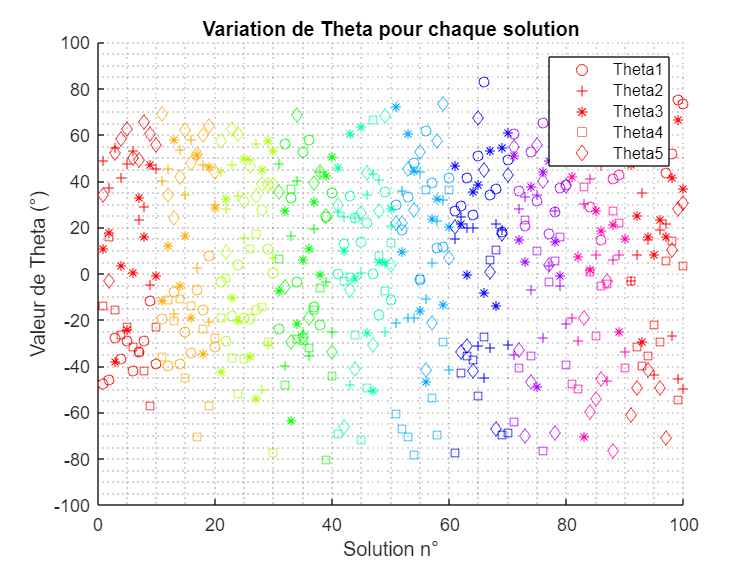





% Créer un tableau de hachage pour mapper chaque numéro de point à une couleur
unique_colors_map = containers.Map('KeyType', 'double', 'ValueType', 'double');
color_index = 1;

for i = 1:size(final_results, 1)
    point_number = final_results(i, 1); % Numéro de point
    if ~isKey(unique_colors_map, point_number)
        unique_colors_map(point_number) = color_index; % Assigner une nouvelle couleur pour chaque nouveau numéro de point
        color_index = color_index + 1;
    end
end

% Convertir les angles en degrés et ajuster les angles à l'intervalle [-180, 180]
final_results_deg = final_results(:, 2:6);
final_results_deg = mod(final_results_deg + 180, 360) - 180;

% Créer une nouvelle figure
figure;

% Boucle sur chaque solution
for i = 1:size(final_results, 1)
    point_number = final_results(i, 1); % Numéro de point
    
    % Récupérer l'index de couleur pour ce numéro de point
    color_index = unique_colors_map(point_number);

    % Définir la couleur en fonction de l'index récupéré
    color = hsv2rgb([(color_index-1)/(size(unique_colors_map, 1)-1), 1, 1]);

    % Tracer le point avec la couleur définie et une forme différente pour chaque valeur de theta
    for joint = 1:5
        % Choisir la forme de marqueur en fonction de la valeur de theta
        switch joint
            case 1
                marker = 'o';
            case 2
                marker = '+';
            case 3
                marker = '*';
            case 4
                marker = 's';
            case 5
                marker = 'd';
        end

        % Tracer le point avec la couleur définie et la forme de marqueur appropriée
        scatter(i, final_results_deg(i, joint), 30, color, marker);
        hold on;
    end
end

% Titre et étiquettes des axes
title('Variation de Theta pour chaque solution');
xlabel('Solution n°');
ylabel('Valeur de Theta (°)');

% Légende
legend('Theta1', 'Theta2', 'Theta3', 'Theta4', 'Theta5');

% Afficher la grille
grid minor;

#### Positions des articulations pour chaque solution

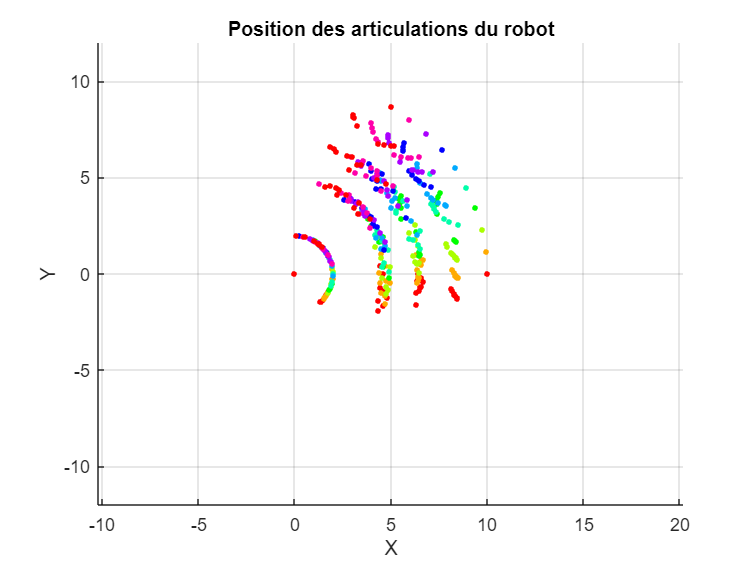

% Créer un tableau de hachage pour mapper chaque numéro de point à une couleur
unique_colors_map = containers.Map('KeyType', 'double', 'ValueType', 'double');
color_index = 1;

for i = 1:size(final_results, 1)
    point_number = final_results(i, 1); % Numéro de point
    if ~isKey(unique_colors_map, point_number)
        unique_colors_map(point_number) = color_index; % Assigner une nouvelle couleur pour chaque nouveau numéro de point
        color_index = color_index + 1;
    end
end

% Créer une nouvelle figure
figure;

hold on; % Garder le graphique actif pour ajouter les données de chaque solution

% Visualisation des configurations du robot
for i = 1:size(final_results, 1)
    % Extraire les angles d'articulation pour cette configuration
    theta1 = final_results(i, 2);
    theta2 = final_results(i, 3);
    theta3 = final_results(i, 4);
    theta4 = final_results(i, 5);
    theta5 = final_results(i, 6);

    % Calcul des positions des articulations du robot avec les valeurs des angles d'articulation calculées
    O = [0, 0]; % Position de l'origine
    A = [a1*cosd(theta1), a1*sind(theta1)]; % Position de l'articulation A
    B = A + [a2*cosd(theta1+theta2), a2*sind(theta1+theta2)]; % Position de l'articulation B
    C = B + [a3*cosd(theta1+theta2+theta3), a3*sind(theta1+theta2+theta3)]; % Position de l'articulation C (extrémité de l'effecteur)
    D = C + [a4*cosd(theta1+theta2+theta3+theta4), a4*sind(theta1+theta2+theta3+theta4)]; % Position de l'articulation C (extrémité de l'effecteur)
    E = D + [a5*cosd(theta1+theta2+theta3+theta4+theta5), a5*sind(theta1+theta2+theta3+theta4+theta5)]; % Position de l'articulation C (extrémité de l'effecteur)

    % Récupérer l'index de couleur pour ce numéro de point
    color_index = unique_colors_map(final_results(i, 1));

    % Définir la couleur en fonction de l'index récupéré
    color = hsv2rgb([(color_index-1)/(size(unique_colors_map, 1)-1), 1, 1]);

    % Tracer le robot pour cette configuration 
    %plot([O(1), A(1), B(1), C(1), D(1), E(1)], [O(2), A(2), B(2), C(2), D(2), E(2)], 'Color', color, 'DisplayName', ['Articulations - Solution ', num2str(final_results(i, 1))]); % Ligne pour les articulations
    scatter([O(1), A(1), B(1), C(1), D(1), E(1)], [O(2), A(2), B(2), C(2), D(2), E(2)], 10, color, 'filled'); % Marques pour les articulations
    % Ajouter les noms des articulations
    %text([O(1), A(1), B(1), C(1), D(1), E(1)], [O(2), A(2), B(2), C(2), D(2), E(2)], {'O', 'A', 'B', 'C', 'D', 'E'}, 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
end 
grid on;

% Calculer les limites des axes
xlim([-12, 12]); 
ylim([-12, 12]);
axis equal

% Configurer le titre et les étiquettes des axes
title('Position des articulations du robot');
xlabel('X');
ylabel('Y');

#### Graphique separe pour chaque articulation

% Créer un graphique distinct pour chaque articulation
figure;

% Créer un tableau de hachage pour mapper chaque numéro de point à une couleur
unique_colors_map = containers.Map('KeyType', 'double', 'ValueType', 'double');
color_index = 1;

for i = 1:size(final_results, 1)
    point_number = final_results(i, 1); % Numéro de point
    if ~isKey(unique_colors_map, point_number)
        unique_colors_map(point_number) = color_index; % Assigner une couleur pour chaque nouveau numéro de point
        color_index = color_index + 1;
    end
end

% Articulation A
subplot(2, 2, 1);
title('Position de l''articulation A');
xlabel('Position X de l''articulation A');
ylabel('Position Y de l''articulation A');
hold on;
% Calculer les positions de l'articulation A pour chaque solution
A_positions = zeros(size(final_results, 1), 2);
for i = 1:size(final_results, 1)
    % Extraire les angles d'articulation pour cette configuration
    theta1 = final_results(i, 2);
    
    % Calculer la position de l'articulation A pour cette solution
    A = [a1*cosd(theta1), a1*sind(theta1)]; % Position de l'articulation A
    A_positions(i, :) = A;
    
    % Récupérer l'index de couleur pour ce numéro de point
    color_index = unique_colors_map(final_results(i, 1));

    % Définir la couleur en fonction de l'index récupéré
    color = hsv2rgb([(color_index-1)/(size(unique_colors_map, 1)-1), 1, 1]);

    % Tracer le point avec la couleur définie
    scatter(A(1), A(2), 5, color, 'filled');
end
grid minor;
xlim([-5, 5]); % Définir les limites des axes X
ylim([-5, 10]); % Définir les limites des axes Y

% Articulation B
subplot(2, 2, 2);
title('Position de l''articulation B');
xlabel('Position X de l''articulation B');
ylabel('Position Y de l''articulation B');
hold on;
% Calculer les positions de l'articulation B pour chaque solution
B_positions = zeros(size(final_results, 1), 2);
for i = 1:size(final_results, 1)
    % Extraire les angles d'articulation pour cette configuration
    theta1 = final_results(i, 2);
    theta2 = final_results(i, 3);
    
    % Calculer la position de l'articulation B pour cette solution
    B = A_positions(i, :) + [a2*cosd(theta1+theta2), a2*sind(theta1+theta2)]; % Position de l'articulation B
    B_positions(i, :) = B;
    
    % Récupérer l'index de couleur pour ce numéro de point
    color_index = unique_colors_map(final_results(i, 1));

    % Définir la couleur en fonction de l'index récupéré
    color = hsv2rgb([(color_index-1)/(size(unique_colors_map, 1)-1), 1, 1]);

    % Tracer le point avec la couleur définie
    scatter(B(1), B(2), 5, color, 'filled');
end
grid minor;
xlim([-5, 5]); % Définir les limites des axes X
ylim([-5, 10]); % Définir les limites des axes Y

% Articulation C
subplot(2, 2, 3);
title('Position de l''articulation C');
xlabel('Position X de l''articulation C');
ylabel('Position Y de l''articulation C');
hold on;
% Calculer les positions de l'articulation C pour chaque solution
C_positions = zeros(size(final_results, 1), 2);
for i = 1:size(final_results, 1)
    % Extraire les angles d'articulation pour cette configuration
    theta1 = final_results(i, 2);
    theta2 = final_results(i, 3);
    theta3 = final_results(i, 4);
    
    % Calculer la position de l'articulation C pour cette solution
    C = B_positions(i, :) + [a3*cosd(theta1+theta2+theta3), a3*sind(theta1+theta2+theta3)]; % Position de l'articulation C
    C_positions(i, :) = C;
    
    % Récupérer l'index de couleur pour ce numéro de point
    color_index = unique_colors_map(final_results(i, 1));

    % Définir la couleur en fonction de l'index récupéré
    color = hsv2rgb([(color_index-1)/(size(unique_colors_map, 1)-1), 1, 1]);

    % Tracer le point avec la couleur définie
    scatter(C(1), C(2), 5, color, 'filled');
end
grid minor;
xlim([-5, 5]); % Définir les limites des axes X
ylim([-5, 10]); % Définir les limites des axes Y

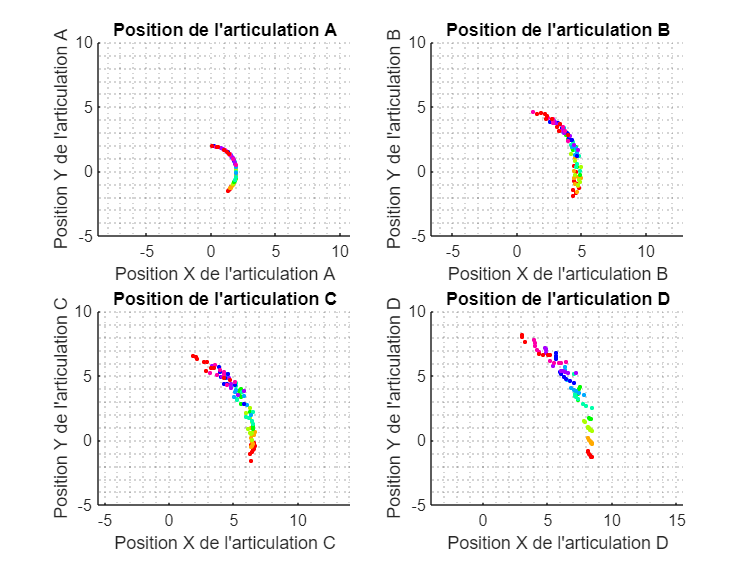

% Articulation D
subplot(2, 2, 4);
title('Position de l''articulation D');
xlabel('Position X de l''articulation D');
ylabel('Position Y de l''articulation D');
hold on;
% Calculer les positions de l'articulation D pour chaque solution
D_positions = zeros(size(final_results, 1), 2);
for i = 1:size(final_results, 1)
    % Extraire les angles d'articulation pour cette configuration
    theta1 = final_results(i, 2);
    theta2 = final_results(i, 3);
    theta3 = final_results(i, 4);
    theta4 = final_results(i, 5);
    
    % Calculer la position de l'articulation D pour cette solution
    D = C_positions(i, :) + [a4*cosd(theta1+theta2+theta3+theta4), a4*sind(theta1+theta2+theta3+theta4)]; % Position de l'articulation D
    D_positions(i, :) = D;
    
    % Récupérer l'index de couleur pour ce numéro de point
    color_index = unique_colors_map(final_results(i, 1));

    % Définir la couleur en fonction de l'index récupéré
    color = hsv2rgb([(color_index-1)/(size(unique_colors_map, 1)-1), 1, 1]);

    % Tracer le point avec la couleur définie
    scatter(D(1), D(2), 5, color, 'filled');
end
grid minor;
xlim([-5, 5]); % Définir les limites des axes X
ylim([-5, 10]); % Définir les limites des axes Y

% Réglage des espacements entre les sous-graphiques
subplot(2, 2, 1); axis equal; 
subplot(2, 2, 2); axis equal; 
subplot(2, 2, 3); axis equal; 
subplot(2, 2, 4); axis equal;

% % Variation de theta pour chaque solution
% %% Définir le nombre total de solutions
% num_solutions = size(final_results, 1);
% 
% % Définir le nombre de lignes et de colonnes pour la grille
% num_rows = 3; % Modifier le nombre de lignes selon le nombre de joints
% num_cols = 2; % Nombre de colonnes pour afficher les graphiques
% 
% % Définir les positions des subplots
% position = reshape(1:num_rows*num_cols, num_cols, num_rows).';
% 
% % Convertir les angles en degrés et ajuster les angles à l'intervalle [-180, 180]
% final_results_deg = final_results(:, 2:6);
% final_results_deg = mod(final_results_deg + 180, 360) - 180;
% 
% % Créer une nouvelle figure
% figure;
% 
% % Choix des couleurs pour chaque point
% %colors = hsv(num_solutions); % Utilisation de l'espace colorimétrique HSV pour obtenir une palette de couleurs variée
% % Générer des couleurs aléatoires pour chaque point
% colors = rand(num_solutions, 3); % RGB
% 
% % Boucle sur chaque angle d'articulation
% for joint = 1:5
%     % Définir la position du subplot dans la grille
%     subplot(num_rows, num_cols, joint);
% 
%     % Titre et étiquettes des axes
%     title(['Variation de Theta', num2str(joint), ' pour chaque solution']);
%     xlabel('Solution');
%     ylabel(['Theta', num2str(joint), '°']); % Modification de l'étiquette en degrés
%     grid minor;
% 
%     hold on; % Garder le graphique actif pour ajouter les données de chaque solution
% 
%     % Tracer les valeurs des angles d'articulation pour chaque solution
%     for i = 1:num_solutions
%         % Extraire l'angle d'articulation ajusté pour cette solution
%         theta_deg = final_results_deg(i, joint);
% 
%         % Tracer l'angle d'articulation pour cette solution
%         plot(i, theta_deg, '+', 'MarkerSize', 5, 'LineWidth', 1, 'Color', colors(i, :),'HandleVisibility', 'off');
% 
%         % Tracer l'angle d'articulation pour ce point avec une couleur unique
%         %plot(i, theta, 'o', 'MarkerSize', 5, 'MarkerFaceColor', , 'MarkerEdgeColor', colors(i, :), 'LineWidth', 1);
%     end
% 
%     % Trouver la valeur maximale et minimale de theta pour cet angle d'articulation
%     max_theta = max(final_results_deg(:, joint));
%     min_theta = min(final_results_deg(:, joint));
% 
%     % Ajouter du texte à la position souhaitée
%     text(-3, max_theta, ['Max: ', num2str(max_theta)], 'Color', 'blue', 'FontSize', 8);
%     text(-3, min_theta, ['Min: ', num2str(min_theta)], 'Color', 'blue', 'FontSize', 8);
%     disp(['Pour theta', num2str(joint), ', Theta max : ', num2str(max_theta), ', Theta min : ', num2str(min_theta)]);
% end
% 
% % Tracer une droite représentant la valeur maximale et minimale de theta pour chaque joint
% for joint = 1:5
%     subplot(num_rows, num_cols, joint);
%     max_theta = max(final_results_deg(:, joint));
%     min_theta = min(final_results_deg(:, joint));
%     plot([1, num_solutions], [max_theta, max_theta], '-b', 'LineWidth', 0.2, 'DisplayName', ['Max Theta', num2str(joint)]);
%     plot([1, num_solutions], [min_theta, min_theta], '-b', 'LineWidth', 0.2, 'DisplayName', ['Min Theta', num2str(joint)]);
% end
% 
% % Légende
% legend('show');
